# Baseball Player Statistics

Instructions are in the task pane to the left. Complete and submit each task one at a time.

## Task 1

players = readtable("../data/baseballPlayers.csv", "TextType", "string");

## Task 2

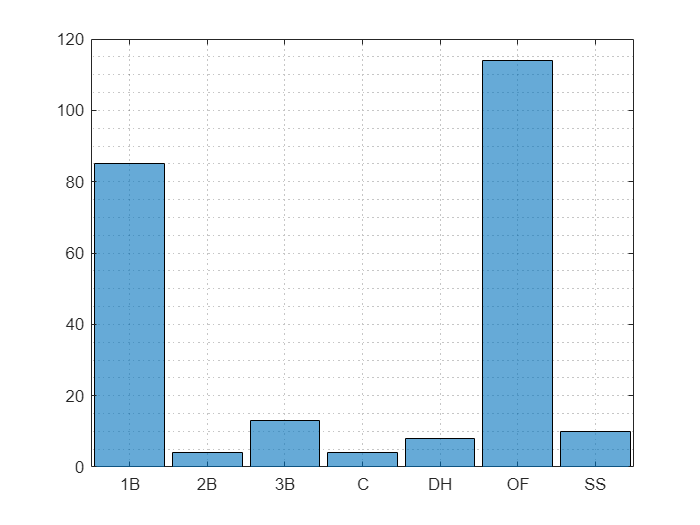

players.Pos = mergecats(categorical(players.Pos), ["OF" "LF" "CF" "RF"], "OF");
histogram(players.Pos)
grid minor

## Task 3

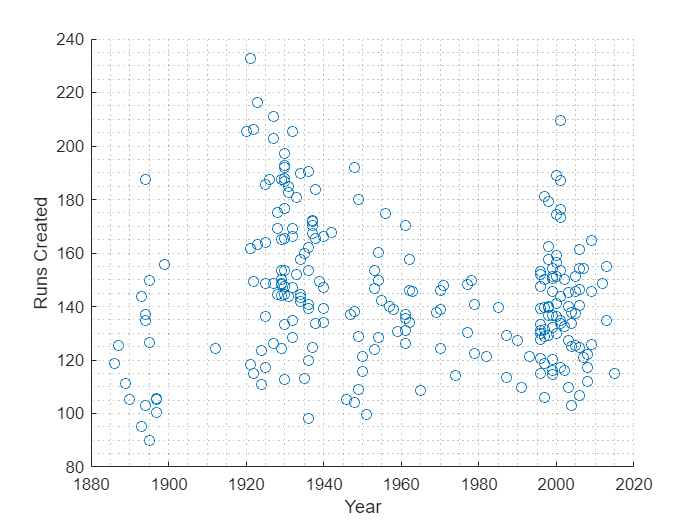

players.TB = players.H + players.B2 + 2*players.B3 + 3*players.HR;
players.RC = (players.H + players.BB).*players.TB./(players.AB + players.BB);
scatter(players.Year, players.RC)
grid minor
xlabel("Year")
ylabel("Runs Created")

## Task 4

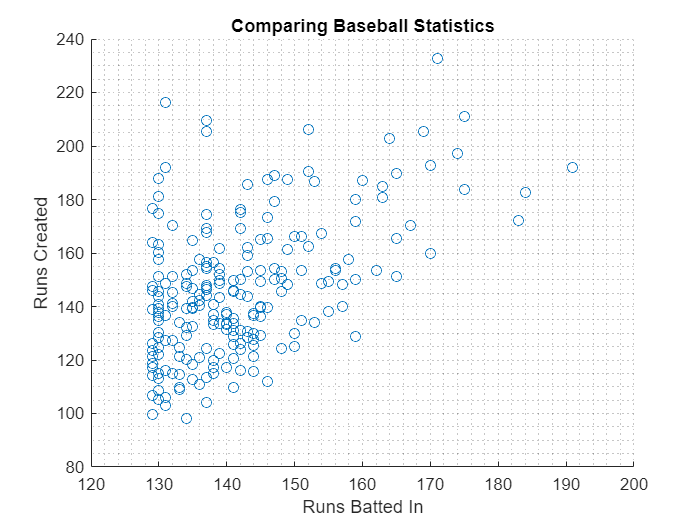

lbEra = players.Year >= 1920;
lbPlayers = players(lbEra, :);
scatter(lbPlayers.RBI, lbPlayers.RC)
grid minor
xlabel("Runs Batted In")
ylabel("Runs Created")
title("Comparing Baseball Statistics")

## Task 5

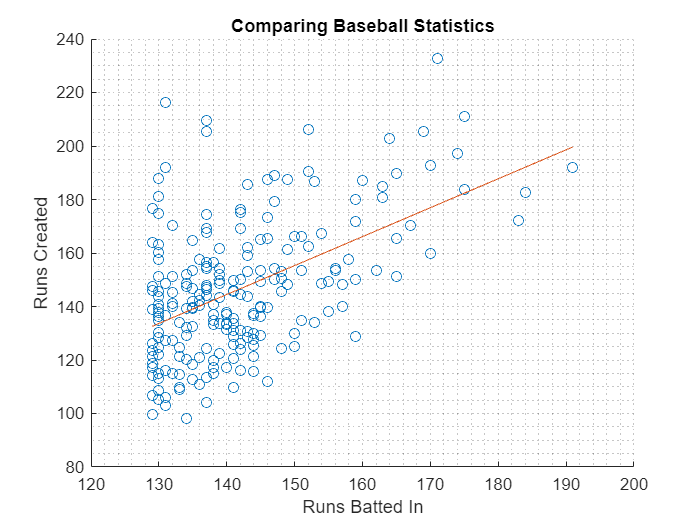

c = polyfit(lbPlayers.RBI, lbPlayers.RC,1);
RBIfit = [min(lbPlayers.RBI) max(lbPlayers.RBI)];
RCfit = polyval(c, RBIfit);
hold on
plot(RBIfit, RCfit)
hold off